## (POC 2) Übersicht über die Daten

Def. der Begriffe

- Zyklus = Alle Injektionen einer Art am Stück

- Runde = je ein Zyklus negativ und ein Zyklus positiv Proben Injektion

% set input and output path
input_path = '../../data/v2/AI_Test/';
output_path = '../../matlab/output';

% input file
%input_file = '192/181601_10112022.csv'; file_name = "192";
%input_file = '193/210226_16112022.csv'; file_name = "193"; 
%input_file = '194/001615_19112022.csv'; file_name = "194";
input_file = '195/201253_25112022.csv'; file_name = "195";
%input_file = '204/205804_23022023.csv'; file_name = "204";
%input_file = '208/221029_17032023.csv'; file_name = "208";
%input_file = '213/230041_07062023.csv'; file_name = "213";
input_file_delimiter = ',';

% read data
full_path = fullfile(input_path, input_file); % compute full path
data = readtable(full_path, Delimiter = input_file_delimiter); % load data

colmap = jet(8);

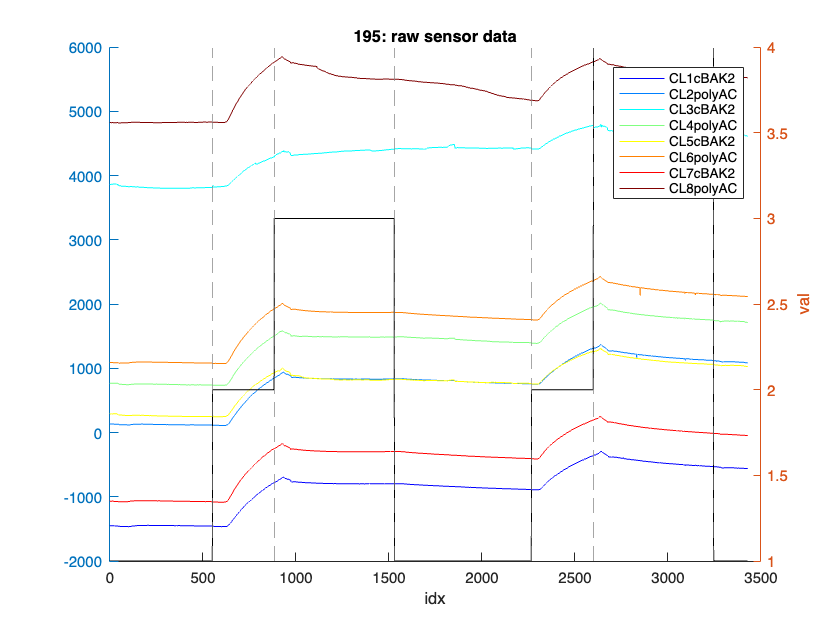

function best_cpt = find_best_cpt(data, mu, sigma)
    o = beast(data, season = 'none');
    cpts = o.trend.cp(~isnan(o.trend.cp));
    prob = o.trend.cpPr(~isnan(o.trend.cp));

    if isempty(cpts)
        disp("[WARNING] trend.cp is empty. BEAST algorithm didnt find any cpts. Setting best_cpt = mu");
        best_cpt = mu;
        return;
    end


    weight = exp( -((cpts - mu).^2) / (2*sigma^2) );
    score = prob .* weight;
    [~, idx] = max(score); 
    
    best_cpt = cpts(idx);
end

Rohdaten im Diagramm:

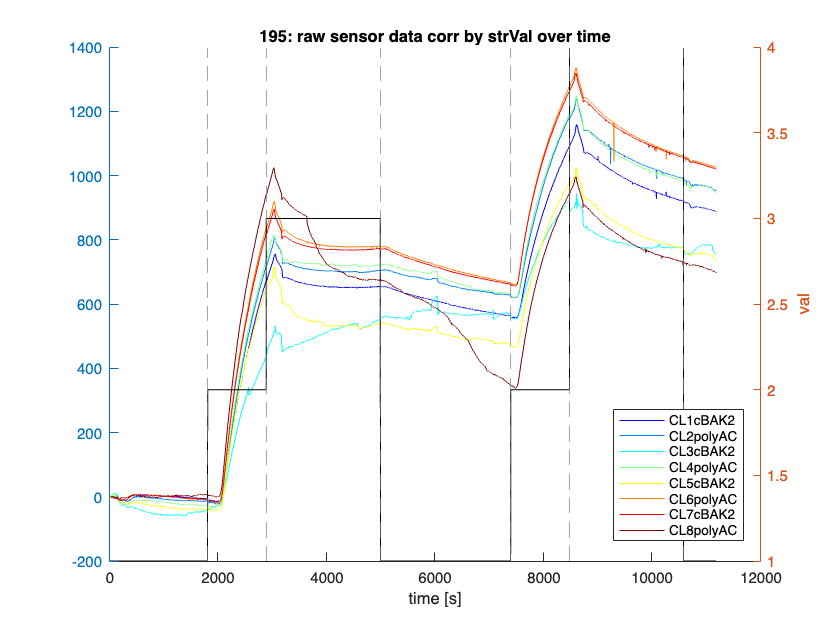

figure; hold on;
yyaxis left;
for i = 1:8
    plot(data{:, i+4}, Color = colmap(i, :), Marker = "none", LineStyle = '-', DisplayName = data.Properties.VariableNames{i+4}); 
end

yyaxis right;
plot(data{:, "Val_"}, Color = 'k', HandleVisibility = 'off');
xline(find(diff(data.Val_) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
xlabel("idx"); ylabel("val"); title(file_name + ": raw sensor data");
legend('show', Interpreter = 'none', Location = 'best');
hold off;

Wir setzten den Anfangswert auf 0

% bring all to 0 (starting value correction)
figure; hold on;
yyaxis left;

n_rounds = 2

for i = 1:8
    strVal = data{1, i+4};
    plot(data.T_s_, data{:, i+4} - strVal, Color = colmap(i, :), Marker = "none", LineStyle = '-', DisplayName = data.Properties.VariableNames{i+4}); 
end
yyaxis right;
plot(data.T_s_, data{:, "Val_"}, Color = 'k', HandleVisibility = 'off');
xline(data.T_s_(find(diff(data.Val_) ~= 0) + 1), '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
xlabel("time [s]"); ylabel("val"); title(file_name + ": raw sensor data corr by strVal over time");
legend('show', Interpreter = 'none', Location = 'best');

#### Filter nach Injektionsart ("Val_")

*Bem: Es gibt vier verschiedene Injektionsarten: Puffer (Val_ = 1), Negativ Probe (2), Erste positiv Probe (3), Zweite positiv Probe (4)*

Wir filtern Zeilen mit Pufferinjektion (Val_ = 1) heraus 

filtered_data = data(data.Val_ ~= 1, :);

und teilen in 2 Runden auf (1 und 2): 

1 mit der ersten negativ Proben Injektion (Val_ = 2) und der ersten positiv Proben Injektion (Val_ = 3) und 2 mit der zweiten negativ Proben Injektion (Val_ = 2) und der zweiten positiv Proben Injektion, anderer Art (Val_ = 4).

% how many rounds?
not_one = data.Val_ ~= 1; one_before = [false; data.Val_(1:end-1) == 1];
n_rounds = sum(not_one & one_before)

Wir kennzeichnen die Injektionsart durch eine weitere Spalte "inj_type" (0 für Negativ, 1 für Positiv) und die Runde durch eine weitere Spalte "round".

inj_type = 2 * ones(height(filtered_data), 1);  % default: 2
inj_type(filtered_data.("Val_") == 2) = 0;
inj_type(ismember(filtered_data.("Val_"), [3, 4])) = 1;
filtered_data.inj_type = inj_type;

Nun fügen wir noch die Spalte "round" hinzu für die Runden

round = 0 * ones(height(filtered_data), 1);  % default: 0
for i = 1:n_rounds
    round(filtered_data.("Inj_") > (i-1)*3 + 1 & filtered_data.("Inj_") < i*3 + 1) = i;
end
filtered_data.round = round;

Wir betrachten die gefilterten Daten und setzten wieder jeweils den Anfangswert auf 0

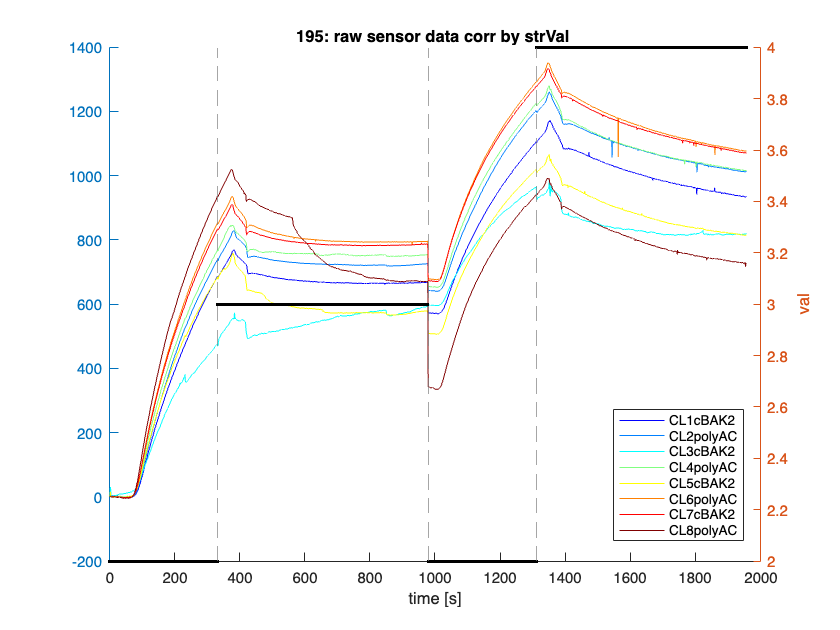

% bring all to 0 (starting value correction)

figure; hold on;
yyaxis left;
for i = 1:8
    strVal = filtered_data{1, i+4};
    plot(filtered_data{:, i+4} - strVal, Color = colmap(i, :), Marker = 'none', LineStyle = '-', DisplayName = filtered_data.Properties.VariableNames{i+4}); 
end
yyaxis right;
plot(filtered_data{:, "Val_"}, '.', Color = 'k', HandleVisibility = 'off');
%plot(filtered_data{:, "round"}, '.', Color = 'r', HandleVisibility = 'off');
xline(find(diff(filtered_data.inj_type) ~= 0) + 1, '--', Color = [0.5, 0.5, 0.5], HandleVisibility = 'off');
xlabel("time [s]"); ylabel("val"); title(file_name + ": raw sensor data corr by strVal ");
legend('show', Interpreter = 'none', Location = 'best');

Wir filtern nun für jede Runde die Negativ-Proben-Injektion (Val_ = 2) heraus und versuchen den einen zugrundeliegenden Trend zu finden. Dazu plotten wir zuerst mal die Negativ-Proben-Injektion:

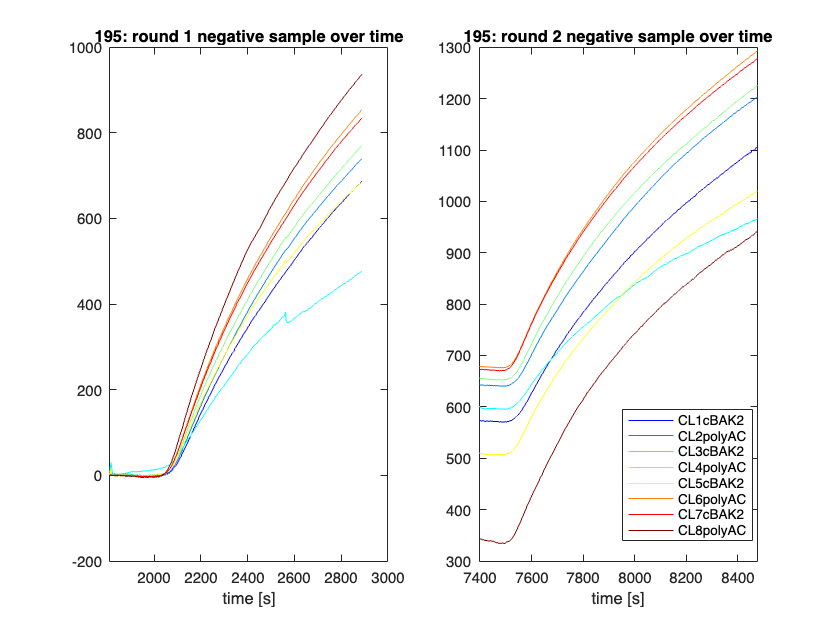

figure;

     fully by 'metadata$startTime' and 'metadata$deltaTime'. But startTime and deltaTime are missing and a
     default value 1 is used for both! 

INFO: To supress printing the parameers in beast(),      set print.options = 0 
INFO: To supress printing the parameers in beast_irreg(),set print.options = 0 
INFO: To supress printing the parameers in beast123(),   set extra.printOptions = 0  
INFO: To supress warning messages in beast(),            set quiet = 1 
INFO: To supress warning messages in beast_irreg(),      set quiet = 1 
INFO: To supress warning messages in beast123(),         set extra.quiet = 1  

%--------------------------------------------------%
%       Brief summary of Input Data                %
%--------------------------------------------------%
Data Dimension: One signal of length 332
IsOrdered     : Yes, ordered in time
IsRegular     : Yes, evenly spaced a

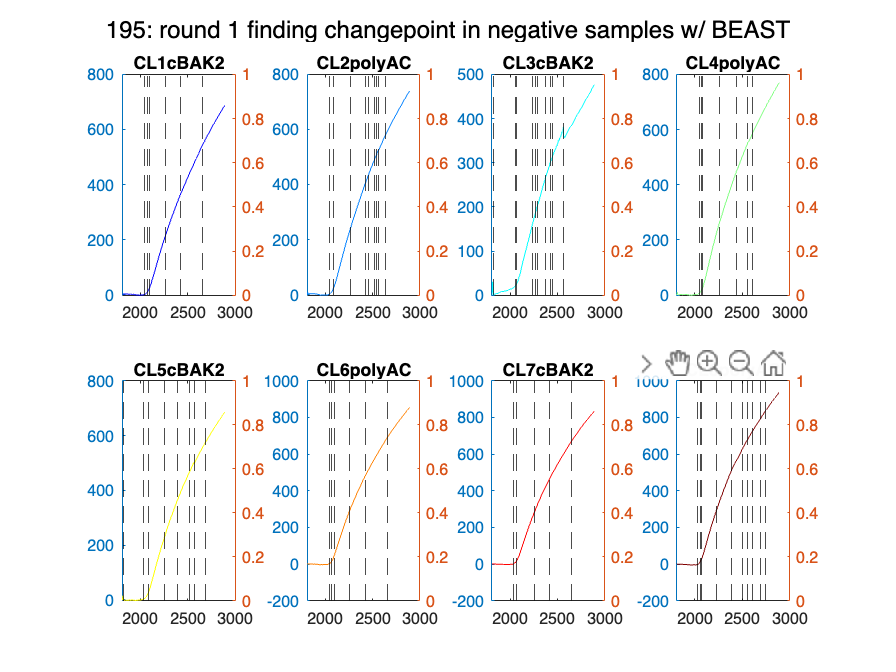

     fully by 'metadata$startTime' and 'metadata$deltaTime'. But startTime and deltaTime are missing and a
     default value 1 is used for both! 

INFO: To supress printing the parameers in beast(),      set print.options = 0 
INFO: To supress printing the parameers in beast_irreg(),set print.options = 0 
INFO: To supress printing the parameers in beast123(),   set extra.printOptions = 0  
INFO: To supress warning messages in beast(),            set quiet = 1 
INFO: To supress warning messages in beast_irreg(),      set quiet = 1 
INFO: To supress warning messages in beast123(),         set extra.quiet = 1  

%--------------------------------------------------%
%       Brief summary of Input Data                %
%--------------------------------------------------%
Data Dimension: One signal of length 333
IsOrdered     : Yes, ordered in time
IsRegular     : Yes, evenly spaced a

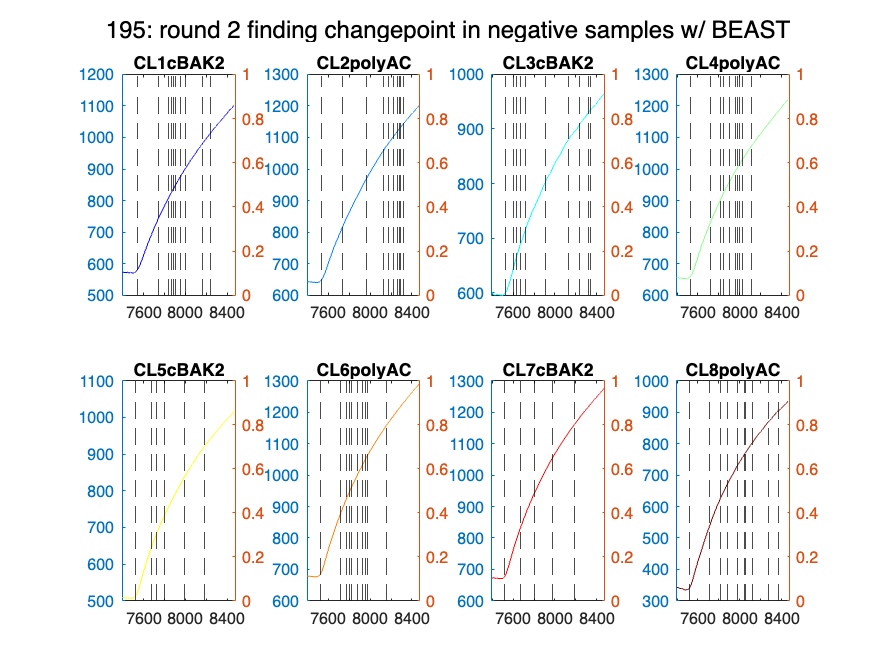

for r = 1:2 % iterate over rounds
    subplot(1,2,r)
    D = filtered_data(filtered_data.round == r & filtered_data.inj_type == 0, :);
    for s = 1:8 % iterate over sensors
        strVal = filtered_data{1, s+4};
        plot(D.T_s_, D{:, s+4}-strVal, Color = colmap(s, :), Marker = 'none', LineStyle = '-', DisplayName = D.Properties.VariableNames{s+4}); 
        hold on;
    end
    xlabel("time [s]"); title(file_name + ": round " + r + " negative sample over time");
    hold off;
end
legend('show', Interpreter = 'none', Location = 'best');

Wir wollen den Verlauf der Negativ-Proben-Injektion mit $$d(t) = 1 - e^{ (- (k_a \cdot c \cdot (t-t_s) )}$$ fitten, wobei

- $$k_a$$ : der Langmuir-Faktor ist;

- $$c \geq 0$$ : die Konzentration ist; und

- $$t_s \geq 0$$ : der Zeitpunkt des Reaktionsbeginn (Drift) ist.

Daher wollen wir zuerst den Startpunkt des Drifts ($$t_s \geq 0$$) finden. Hierzu haben wir verschiedende Ansätze getestet:

- Betrachten der Ableitung mit `diff` und evtl. Glätten der Ableitungsfunktion mit `smooth(method='moving') `und Füllen von Ausreissern mit `filloutliers(fillmethod='center')` um Punkt des Anstiegs zu finden. Das Problem ist jedoch, dass der (einfach zu findende) Höhepunkt erst etwa in der Hälfte des Anstiegs liegt (Ort des stärksten Anstiegs) und man mit jeder weiteren Ableitung zwar mit 2^n näher an den tatsächlichen Startpunkt kommt die Ableitungen jedoch sehr schnell abflachen so dass Veränderungen (und Höhepunkte kaum erkennbar sind)

- Berechnen der "Wechselpunkte" mit `findchangepts`. Diese versucht jedoch die Funktion in zwei Teile zu teilen mit dem ähnlichsten (kleinstes Bestimmtheitsmass) Mittelwert. Gegeben der Form der Funktion führt das zu einem Wechselpunkt ziemlich genau in der Mitte des Anstiegs.

- Als praktisch hat sich der *BEAST* (*Bayesian Change-Point Detection and Time Series Decomposition*) Algorithmus erwiesen, welcher im Folgenden auch für die Startpunktbestimmung angewendet wird.

%% for r = 1:2 % iterate over rounds
%% end
for r = 1:2
    figure(r);
    title(file_name + ": round" + r + " negative samples and 1st derivative over time");
    D = filtered_data(filtered_data.round == r & filtered_data.inj_type == 0, :); % filter data
    for s = 1:8 % iterate over sensors
        subplot(2,4,s)
        strVal = filtered_data{1, s+4}; % starting value (for correction)
        mu = 75; % mean
        sigma = 5; % std dev
        %best = find_best_cpt(D{:, s+4}, mu, sigma);
        o = beast(D{:, s+4}, season = 'none');
        cpts = o.trend.cp(~isnan(o.trend.cp));
        prob = o.trend.cpPr(~isnan(o.trend.cp));

        %weight = exp( -((cpts - mu).^2) / (2*sigma^2) );
        %score = prob .* weight;
    
        yyaxis left; plot(D.T_s_, D{:, s+4}-strVal, Color = colmap(s, :), Marker = 'none', LineStyle = '-'); % plot data
        hold on; 
        
        yyaxis right; %xline(D.T_s_(best), '--r', HandleVisibility = 'off');
        for i = 1:length(cpts)
            xline(D.T_s_(cpts(i)), '--k', HandleVisibility = 'off');
        end
        title(D.Properties.VariableNames{s+4}); %legend("data", "dy (smoothed)", "dyy (smoothed)");
    end
    hold off;
    sgtitle(file_name + ": round " + r + " finding changepoint in negative samples w/ BEAST");
end

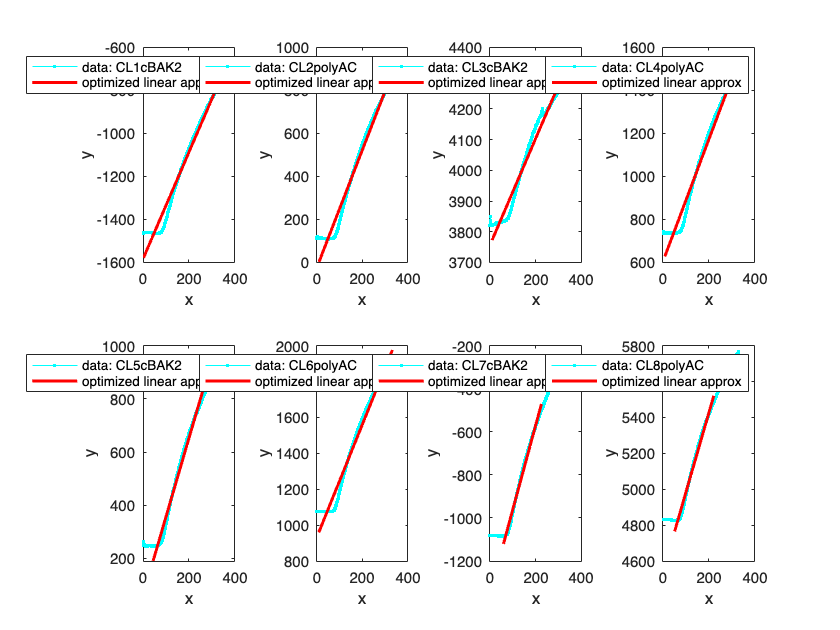

%for r = 1:2 % iterate over rounds
%    D = filtered_data(filtered_data.round == r & filtered_data.inj_type == 0, :);
%    for s = 1:8 % iterate over sensors
%       
%    end
%end

D = filtered_data(filtered_data.round == 1 & filtered_data.inj_type == 0, :);
figure;
for s = 1:8 % iterate over sensors
    data_array = table2array(D(:, s+4));
    x = (1:length(data_array))';
    y = data_array;

    y_smooth = smooth(y, 5);

    dy = diff(y_smooth); % calc 1st derivative
    threshold = 0.01; % inclination threshold
    window = 5; % window for steady inclination

    start_idx = NaN;
    for i = 1:length(dy)-window
        if all(dy(i:i+window-1) > threshold)
            start_idx = i;
            break;
        end

    end
    
    bestR2 = -Inf;
    bestStart = 1;
    bestModel = [];
    minLength = length(data_array) * .5;  % min points for regression
    
    for j = (start_idx + minLength):length(x)
        xi = x(start_idx:j);
        yi = y(start_idx:j);
    
        p = polyfit(xi, yi, 1); % linear regression
        yfit = polyval(p, xi); % on data
    
        SSres = sum((yi - yfit).^2); % calculate r2
        SStot = sum((yi - mean(yi)).^2);   
        R2 = 1 - (SSres / SStot); 
    
        if R2 > bestR2 % replace model if better then previous
            bestR2 = R2;
            bestEnd = j;
            bestModel = p;
        end
    end
    % plot
    subplot(2,4,s)
    plot(x, y, 'c.-'); hold on;
    plot(x(start_idx:bestEnd), polyval(bestModel, x(start_idx:bestEnd)), 'r-', 'LineWidth', 2);
    legend("data: " + D.Properties.VariableNames{s+4}, "optimized linear approx");
    xlabel("x"); ylabel("y");
    %disp("sensor: " + D.Properties.VariableNames{s+4} + newline + ...
    %    "best start index: " + start_idx + newline +...
    %    "best fit from index from " + start_idx + " to " + bestEnd + newline +  ...
    %    "slope: " + bestModel(1) + " intercept: " + bestModel(2) + newline + ...
    %    "best r2: "+ bestR2)
end
%title("Optimized linear approx to data cut");